#          Computational Electromagnetics 

##                                             Hw4

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1401/09/1         

clear; clc; close all;

## 1) Q:       3.44 

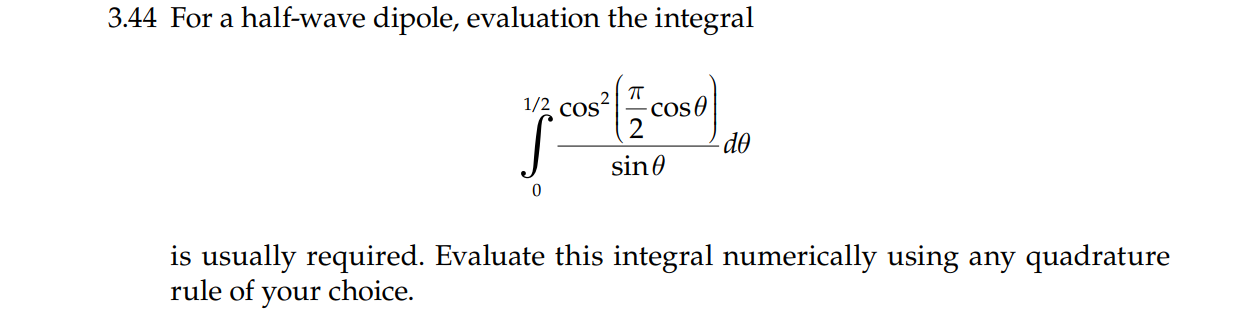

- Correct 1/2 to pi in the integration interval!

## Trapezoidal rule

------ >>>>>    ذوزنقیه ای

a=0+eps;
b=pi-eps;
h=1/5*(b-a)/12;
h1=h;
% x0=a:h/5:b;

L=ceil((b-a)/h);
y=zeros(L+1,1);


syms x
f(x)=((cos(pi/2*cos(x))).^2)./sin(x);

    try
    for i=1:L+1
       if(i==1) 
       y(i)=1/2*double(f(a+(i-1)*h));
       elseif(i==L+1)
           y(i)=1/2*double(f(a+(i-1)*h));
       else
           y(i)=double(f(a+(i-1)*h));
       end
    end
    catch
        % continue
    end
format long    
Result_1=h*sum(y,'all') % Zoonagheyi Solution

Result_1 =    1.218826773800705

double(int(f(x),x,a,b)) % Symbolic Integration SOlution --> Kind of Exact

ans =    1.218826696528612

## Plotting:

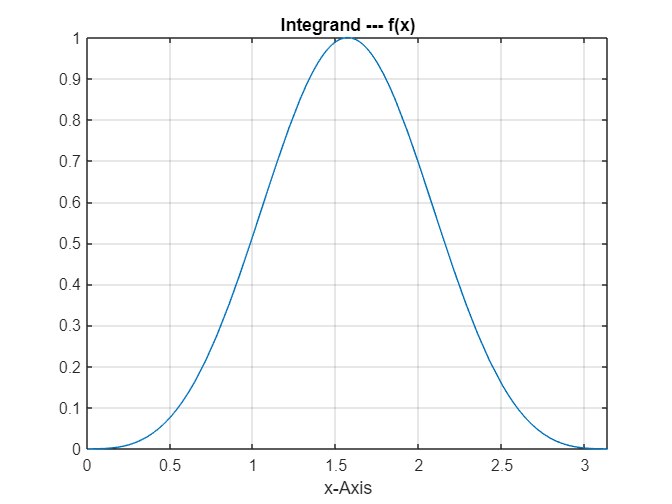

figure(1)
fplot(f(x),[0,pi])
grid on
xlabel("x-Axis")
title("Integrand --- f(x)")

% Trying Integration using different h values:

h=1/10*(b-a)/12;
h2=h;
L=ceil((b-a)/h);
y=zeros(L+1,1);

    try
    for i=1:L+1
       if(i==1) 
       y(i)=1/2*double(f(a+(i-1)*h));
       elseif(i==L+1)
           y(i)=1/2*double(f(a+(i-1)*h));
       else
           y(i)=double(f(a+(i-1)*h));
       end
    end
    catch
        % continue
    end
Result_2=h*sum(y,'all'); % Zoonagheyi Solution
format long
disp("with h = "+h+" Integration will result in:  ");

with h = 0.02618 Integration will result in:  


disp(Result_2)

   1.218826701358121


h=1/20*(b-a)/12;
h3=h;
L=ceil((b-a)/h);
y=zeros(L+1,1);

    try
    for i=1:L+1
       if(i==1) 
       y(i)=1/2*double(f(a+(i-1)*h));
       elseif(i==L+1)
           y(i)=1/2*double(f(a+(i-1)*h));
       else
           y(i)=double(f(a+(i-1)*h));
       end
    end
    catch
        % continue
    end
Result_3=h*sum(y,'all'); % Zoonagheyi Solution
format long
disp("with h = "+h+" Integration will result in:  ");

with h = 0.01309 Integration will result in:  


disp(Result_3)

   1.218826696830457


## Convergence of Trapezoidal rule

Result_3 , h3

Result_3 =    1.218826696830457

h3 =    0.013089969389957

Result_2 , h2

Result_2 =    1.218826701358121

h2 =    0.026179938779915

Result_1 , h1

Result_1 =    1.218826773800705

h1 =    0.052359877559830

Diff_R = [Result_1, Result_2 , Result_3]  - Result_1;
disp(Diff_R)

   1.0e-07 *
                   0  -0.724425832654418  -0.769702479530565


## Sympson


a=0;
b=pi;
n=10;

Result_symp_1 = Symp_int_mine(a,b,5);
Result_symp_2 = Symp_int_mine(a,b,10);
Result_symp_3 = Symp_int_mine(a,b,50);
Result_symp_4 = Symp_int_mine(a,b,100);
Result_symp_5 = Symp_int_mine(a,b,500);
Result_symp_6 = Symp_int_mine(a,b,1000);
Result_symp_7 = Symp_int_mine(a,b,2e3);

Result_symps = [Result_symp_1 , Result_symp_2 ,Result_symp_3, Result_symp_4 ,Result_symp_5 , Result_symp_6 ,Result_symp_7];

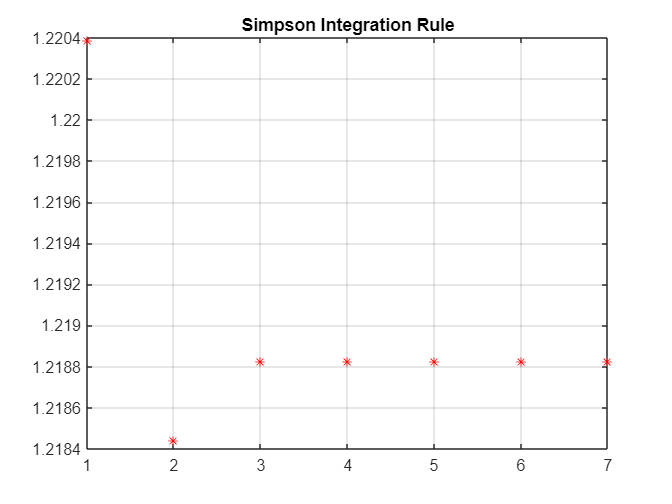

figure(2)
plot(Result_symps,'r*')
title("Simpson Integration Rule")
grid on

Diff_R_symp  = Result_symps - Result_symps(1);
disp(Diff_R_symp)% Valid till 3 digits

  Columns 1 through 4
                   0  -0.001943839978225  -0.001558564686667  -0.001557963839571
  Columns 5 through 7
  -0.001557923845864  -0.001557923785777  -0.001557923782021


## Gauss:

a=0;
b=pi;

Y = My_Gauss_int(a,b) % Gauss Based on Polynomials

Y =    3.141592653589793   0.546789753636908   1.443901206512115


Gauss_Ns = [2,3,5,10,20,30]; 
Gauss_leg_Res_1  = My_Gauss_Legendre_int(a,b,Gauss_Ns(1));
Gauss_leg_Res_2  = My_Gauss_Legendre_int(a,b,Gauss_Ns(2));
Gauss_leg_Res_3  = My_Gauss_Legendre_int(a,b,Gauss_Ns(3));
Gauss_leg_Res_4  = My_Gauss_Legendre_int(a,b,Gauss_Ns(4));
Gauss_leg_Res_5  = My_Gauss_Legendre_int(a,b,Gauss_Ns(5));
Gauss_leg_Res_6  = My_Gauss_Legendre_int(a,b,Gauss_Ns(6));

Result_Gauss_Legendre = [ Gauss_leg_Res_1 , Gauss_leg_Res_2 , Gauss_leg_Res_3 , ...
    Gauss_leg_Res_4 ,Gauss_leg_Res_5 ,Gauss_leg_Res_6  ] ; 

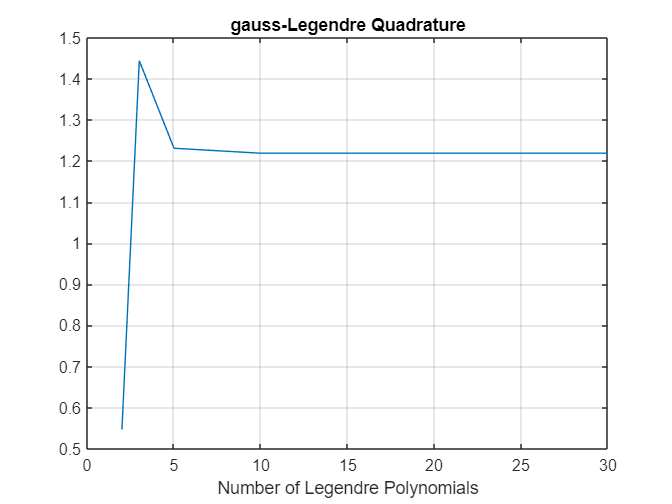


figure()
plot(Gauss_Ns , Result_Gauss_Legendre);
grid on
title("gauss-Legendre Quadrature")
xlabel("Number of Legendre Polynomials")

Diff_R_Gauss_Legendre = Result_Gauss_Legendre - double(int(f(x),x,a,b));
disp(Diff_R_Gauss_Legendre);

  Columns 1 through 4
  -0.672036942891704   0.225074509983503   0.012068414954214  -0.000001341846936
  Columns 5 through 6
  -0.000000000000000                   0


function Sum = My_Gauss_Legendre_int(a,b,N)

syms x
f(x)=((cos(pi/2*cos(x))).^2)./sin(x);

% g(x)=(b-a)/2*f(1/2*((b-a)*x+(b-a)));

% Legendre Polynomials  --> Usable in [-1,1]
% P_m = zeros(1,N);
P_m(1) = sym(1) ;
P_m(2) = x;
for m=2:N-1

P_m(m+1) = (2*(m-1)+1)/((m-1)+1)*x*P_m(m) - ((m-1))/((m-1)+1)*P_m(m-1)  ; 

end

X_roots = cell(1,N);
for m = 1:N
roots = vpasolve(legendreP(m,x) == 0);
X_roots{1,m} = double(roots);
end

%% Find H for m = N;
H = zeros(1,N);
p_roots  = X_roots{1,N};
Leg_polys(x) = P_m(1,N);
Sum = 0;

for m=1:N
    
    H(1,m) = 2*(1-p_roots(m)^2) / ( ( N )^2 *  ( double(Leg_polys(p_roots(m))) )^2  );

    if (   (b-a)/2*p_roots(m) + (b+a)/2 == 0 )
    Sum  = Sum +0; % Function Value at 0 is 0!    
    else
    Sum = Sum + H(1,m)*double(  f( (b-a)/2*p_roots(m) + (b+a)/2   )   ) ;
    end

end

Sum  = (b-a)/2 * Sum;




end



function Y = My_Gauss_int(a,b)

syms x
f(x)=((cos(pi/2*cos(x))).^2)./sin(x);

g(x)=(b-a)/2*f(1/2*((b-a)*x+(b-a)));
%2 Point
x=sqrt(3)/3;
y2=double(g(x))+double(g(-x));
%1 Point
x=0;
y1=2*double(g(x));
% 3Point
x1=-sqrt(3/5);
x2=0;
x3=-x1;
y3=1/9*(5*double(g(x1))+8*double(g(x2))+5*double(g(x3)));

Y = [y1,y2,y3];
end



Sympson Integration Function:

function Result = Symp_int_mine(a,b,n)
h=((b-a)/n);
y=zeros(n,1);

syms x
f(x)=((cos(pi/2*cos(x))).^2)./sin(x);


try
for i=1:n+1
    if((i==1)||(i==n+1))
        y(i)= f(a+(i-1)*h);
    elseif(mod(i,2)==0)
        y(i)= 4*f(a+(i-1)*h);
    else
        y(i)= 2*f(a+(i-1)*h);
    end
end
catch
    %continue
end
Result=h/3*sum(y,'all');
end




